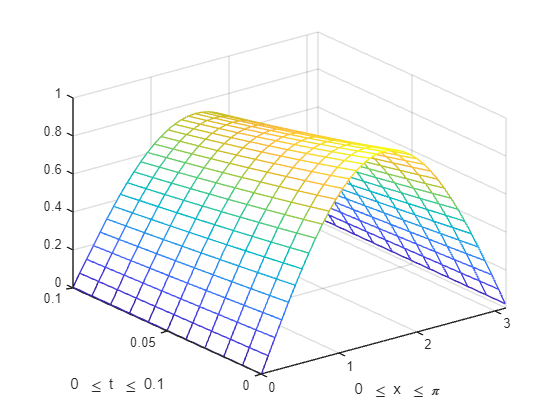

delta_x=0.52/6;
delta_t=0.01;
alpha=3;
u=(0:delta_x:pi).';
u_init=sin(u);
t=0:delta_t:0.1;
r=alpha*delta_t/(delta_x)^2;

n=length(u_init);

A=zeros(n,n);
A(1,1)=1;
A(n,n)=1;
for i=2:1:n-1
   A(i,i)=2*(1+r);
   A(i,i-1)=-r;
   A(i,i+1)=-r;
end

B=zeros(n,n);
B(1,1)=1;
B(n,n)=1;
for i=2:1:n-1
   B(i,i)=2*(1-r);
   B(i,i-1)=r;
   B(i,i+1)=r;
end

%A,B
n1=0.1/delta_t+1;
u_loop=u_init;
u_combined=zeros(n,n1);
u_combined(1:n,1)=u_init;
for i=1:1:n1-1
    u_new=update(u_loop,A,B);
    u_loop=u_new;
    u_combined(1:n,i+1)=u_loop;
    mesh(u.',t(1,1:i+1),u_combined(1:n,1:i+1).')
    xlabel('0 \leq x \leq \pi') 
    ylabel('0 \leq t \leq 0.1') 
    xlim([0, pi]);  % Set xmin and xmax as your desired limits
    ylim([0, 0.1]);
    pause(0.1);
end

function u_new=update(u,A,B)
    u_new=inv(A)*B*u;
end
